# Best Subset Selection

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
addpath(fpath,dpath);
load 'Stage 6 Regression Second Try'\'saved data'\regression\Tp_14_sorted.mat
load 'Stage 6 Regression Second Try'\'saved data'\regression\Tv_13_sorted.mat
load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat

Store results in structure arrays: bestSubset & tempStruct

**bestSubset**: num_sensors, combination, Tv_model, Tv_MSE, Tp_14_sorted_fitted, Tp_model, Tp_MSE

**tempStruct**:                         combination, Tv_model, Tv_MSE, Tp_14_sorted_fitted, Tp_model, Tp_MSE

for i = 1:13
    C = nchoosek(1:13,i); % 13选 i, 每一行表示一种组合
    bestSubset(i).num_sensors = i;
    
    for j = 1:height(C) % loop through every possible combination for i kept sensors
        idx = C(j,:);
        tempStruct(j).combination = idx;

        % train cross-validated quadratic linear model to predict T_{max}
        [trained_mdl,~,vMSE] = train_Tv_model(Tv_13_sorted,idx);
        tempStruct(j).Tv_model = trained_mdl;
        tempStruct(j).Tv_MSE = vMSE;

        % predict T_max with the trained model
        yfit = trained_mdl.predictFcn(Tv_13_sorted(:,1:end-1));
        yfit = array2table(yfit,"VariableNames","T_value");
        Tp_14_sorted(:,"T_value") = yfit;
        tempStruct(j).Tp_14_sorted_fitted = Tp_14_sorted;

        % train cross-validated quadratic linear model to predict beta_{T_{max}}
        % note: may need to perform Ridge regression
        [trained_mdl,~,vMSE] = train_Tp_model(Tp_14_sorted,idx);
        tempStruct(j).Tp_model = trained_mdl;
        tempStruct(j).Tp_MSE = vMSE;
        
    end

    % select the sensor combination that produces the best prediction of T_max position
    Tp_MSE = zeros(height(C),1);
    for j = 1:height(C)
        Tp_MSE(j) = tempStruct(j).Tp_MSE;
    end
    [~,minIdx] = min(Tp_MSE);

    % 将选中的行填入bestSubset(i)
    bestSubset(i).combination = tempStruct(minIdx).combination;
    bestSubset(i).Tv_model = tempStruct(minIdx).Tv_model;
    bestSubset(i).Tv_MSE = tempStruct(minIdx).Tv_MSE;
    bestSubset(i).Tp_14_sorted_fitted = tempStruct(minIdx).Tp_14_sorted_fitted;
    bestSubset(i).Tp_model = tempStruct(minIdx).Tp_model;
    bestSubset(i).Tp_MSE = tempStruct(minIdx).Tp_MSE;

end
bestSubset % saved as 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

bestSubset = 1×13 struct array with fields:
    num_sensors
    combination
    Tv_model
    Tv_MSE
    Tp_14_sorted_fitted
    Tp_model
    Tp_MSE


#### Plot validation MSE & RMSE for all possible number of sensors

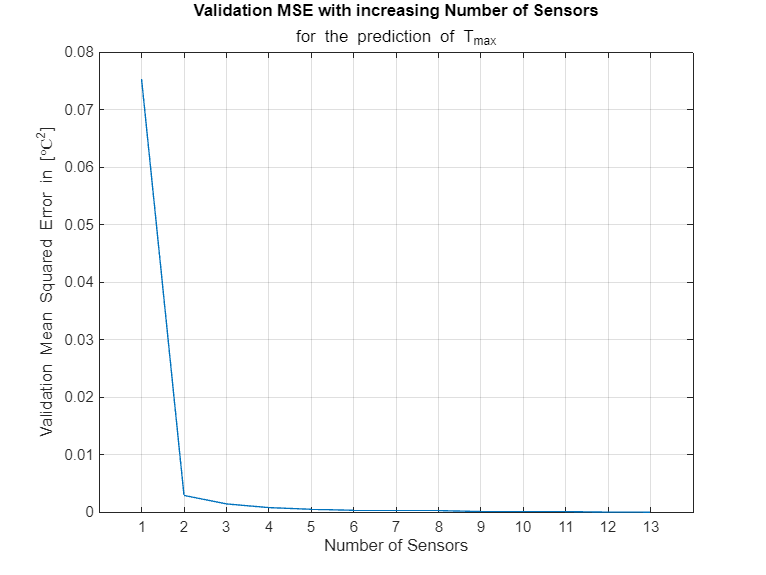

load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

Tv_MSE = zeros(1,numel(bestSubset));
Tp_MSE = zeros(1,numel(bestSubset));

for i = 1:numel(bestSubset)
    Tv_MSE(i) = bestSubset(i).Tv_MSE;
    Tp_MSE(i) = bestSubset(i).Tp_MSE;
end

% plot MSE
figure
plot(1:13,Tv_MSE), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Mean Squared Error in [{℃}^2]")
title("Validation MSE with increasing Number of Sensors",...
    "for the prediction of T_{max}")

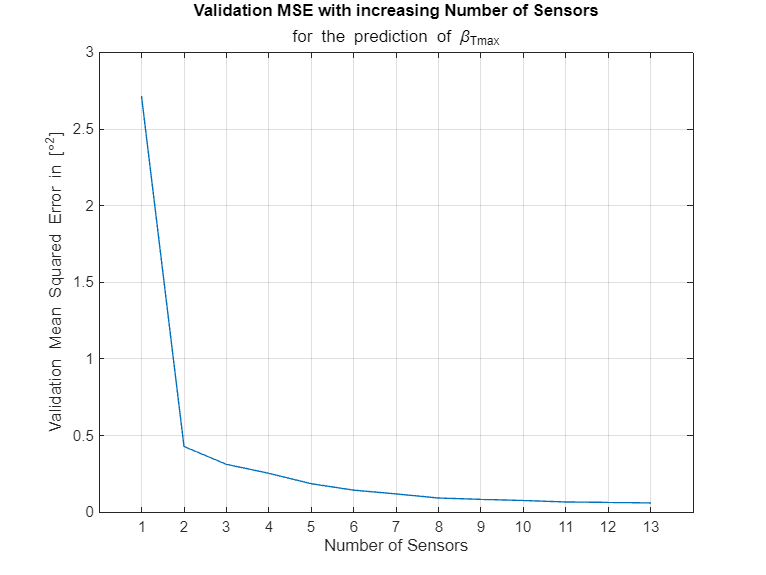


figure
plot(1:13,Tp_MSE), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Mean Squared Error in [{°}^2]")
title("Validation MSE with increasing Number of Sensors",...
    "for the prediction of \beta_{Tmax}")

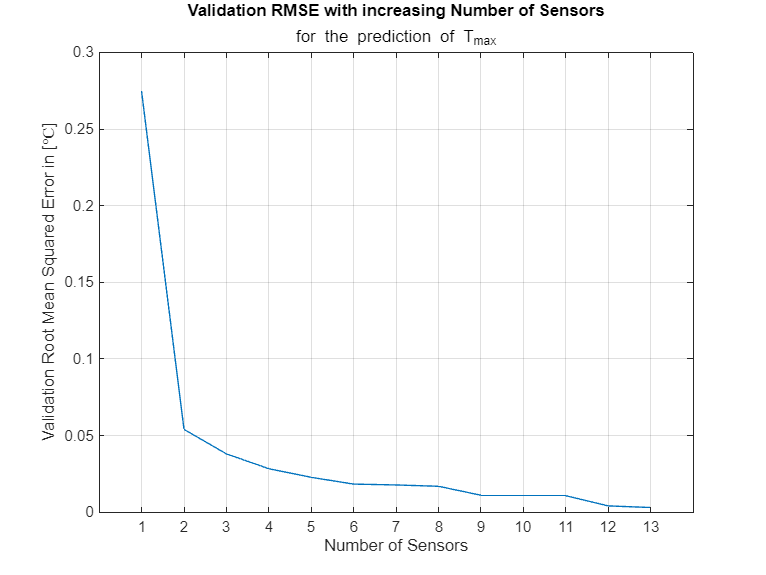


% plot RMSE
figure
plot(1:13,sqrt(Tv_MSE)), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [℃]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of T_{max}")

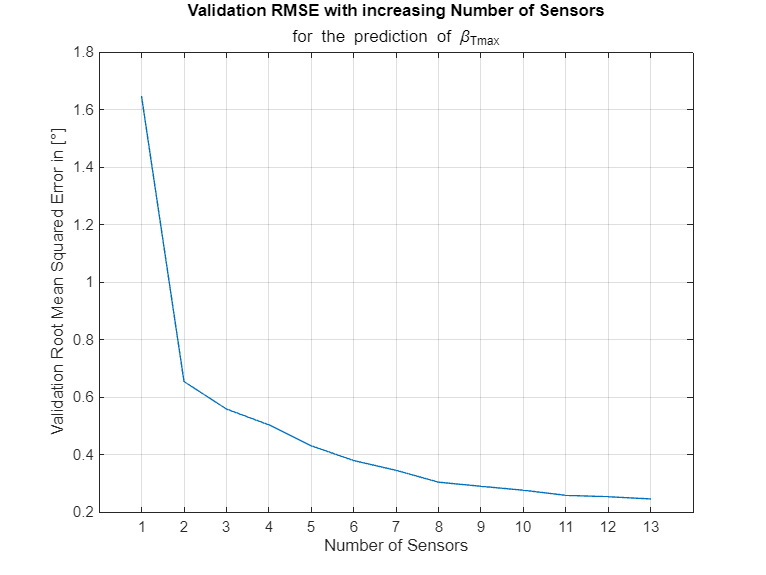


figure
plot(1:13,sqrt(Tp_MSE)), grid on
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [°]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of \beta_{Tmax}")

#### Calculate h_min for all possible number of sensors

load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
h_min_true = h_min_sorted{:,:};

% predict beta_Tmax with the trained models
for i = 1:numel(bestSubset)
    mdl = bestSubset(i).Tp_model;
    Tp14_tbl = bestSubset(i).Tp_14_sorted_fitted;
    yfit = mdl.predictFcn(Tp14_tbl(:,1:end-1)); % predicted beta_Tmax
    h_min_fit = beta_to_hmin(yfit,120,1.6667,0.25);
    bestSubset(i).h_min_fit = h_min_fit;

    % calculate MSE for h_min
    err = h_min_true - h_min_fit; % h_min_true的顺序对应T_max_positions_sorted的顺序
    MSE = sum(err.^2)/length(h_min_fit);
    bestSubset(i).h_MSE = MSE;
end

ans = 121.5213

bestSubset % saved as 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

Add residuals to the bestSubset

load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
h_min_true = h_min_sorted{:,:};

% predict beta_Tmax with the trained models
for i = 1:numel(bestSubset)
    mdl = bestSubset(i).Tp_model;
    Tp14_tbl = bestSubset(i).Tp_14_sorted_fitted;
    yfit = mdl.predictFcn(Tp14_tbl(:,1:end-1)); % predicted beta_Tmax
    h_min_fit = beta_to_hmin(yfit,120,1.6667,0.25);
    %bestSubset(i).h_min_fit = h_min_fit;

    % calculate MSE for h_min
    err = h_min_true - h_min_fit; % h_min_true的顺序对应T_max_positions_sorted的顺序
    bestSubset(i).Residuals = err;
    %MSE = sum(err.^2)/length(h_min_fit);
    %bestSubset(i).h_MSE = MSE;
end
bestSubset % saved as 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

bestSubset = 1×13 struct array with fields:
    num_sensors
    combination
    Tv_model
    Tv_MSE
    Tp_14_sorted_fitted
    Tp_model
    Tp_MSE
    h_min_fit
    h_MSE
    Residuals


Plot RMSE for h_min

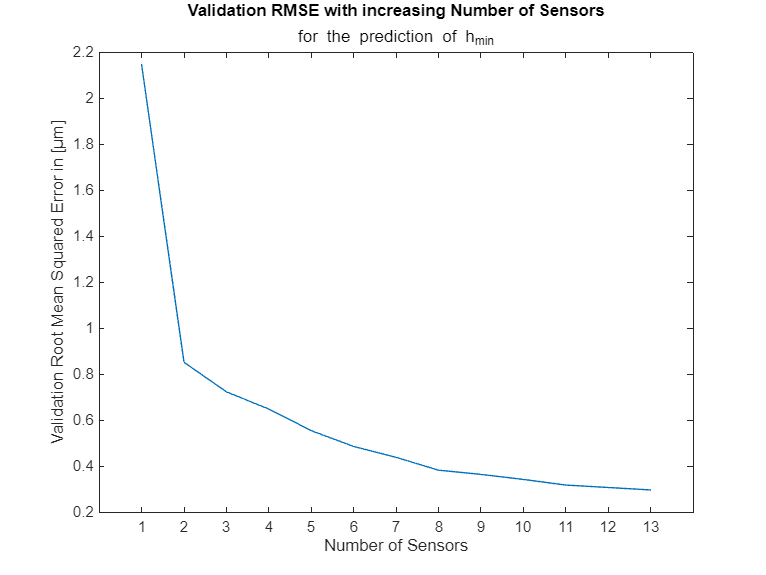

h_MSE = zeros(1,numel(bestSubset)); % column vector

for i = 1:numel(bestSubset)
    h_MSE(i) = bestSubset(i).h_MSE;
end

figure
plot(1:13,sqrt(h_MSE))
xlabel("Number of Sensors"), xticks(1:13), xlim([0,14])
ylabel("Validation Root Mean Squared Error in [μm]")
title("Validation RMSE with increasing Number of Sensors",...
    "for the prediction of h_{min}")

#### Plot h_min_true & h_min_fit together for all possible number of sensors

Number of Sensors: 1


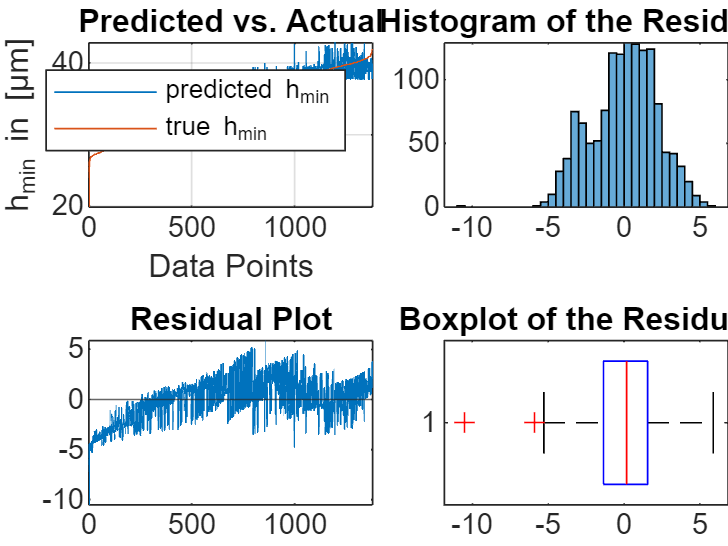

Number of Sensors: 2


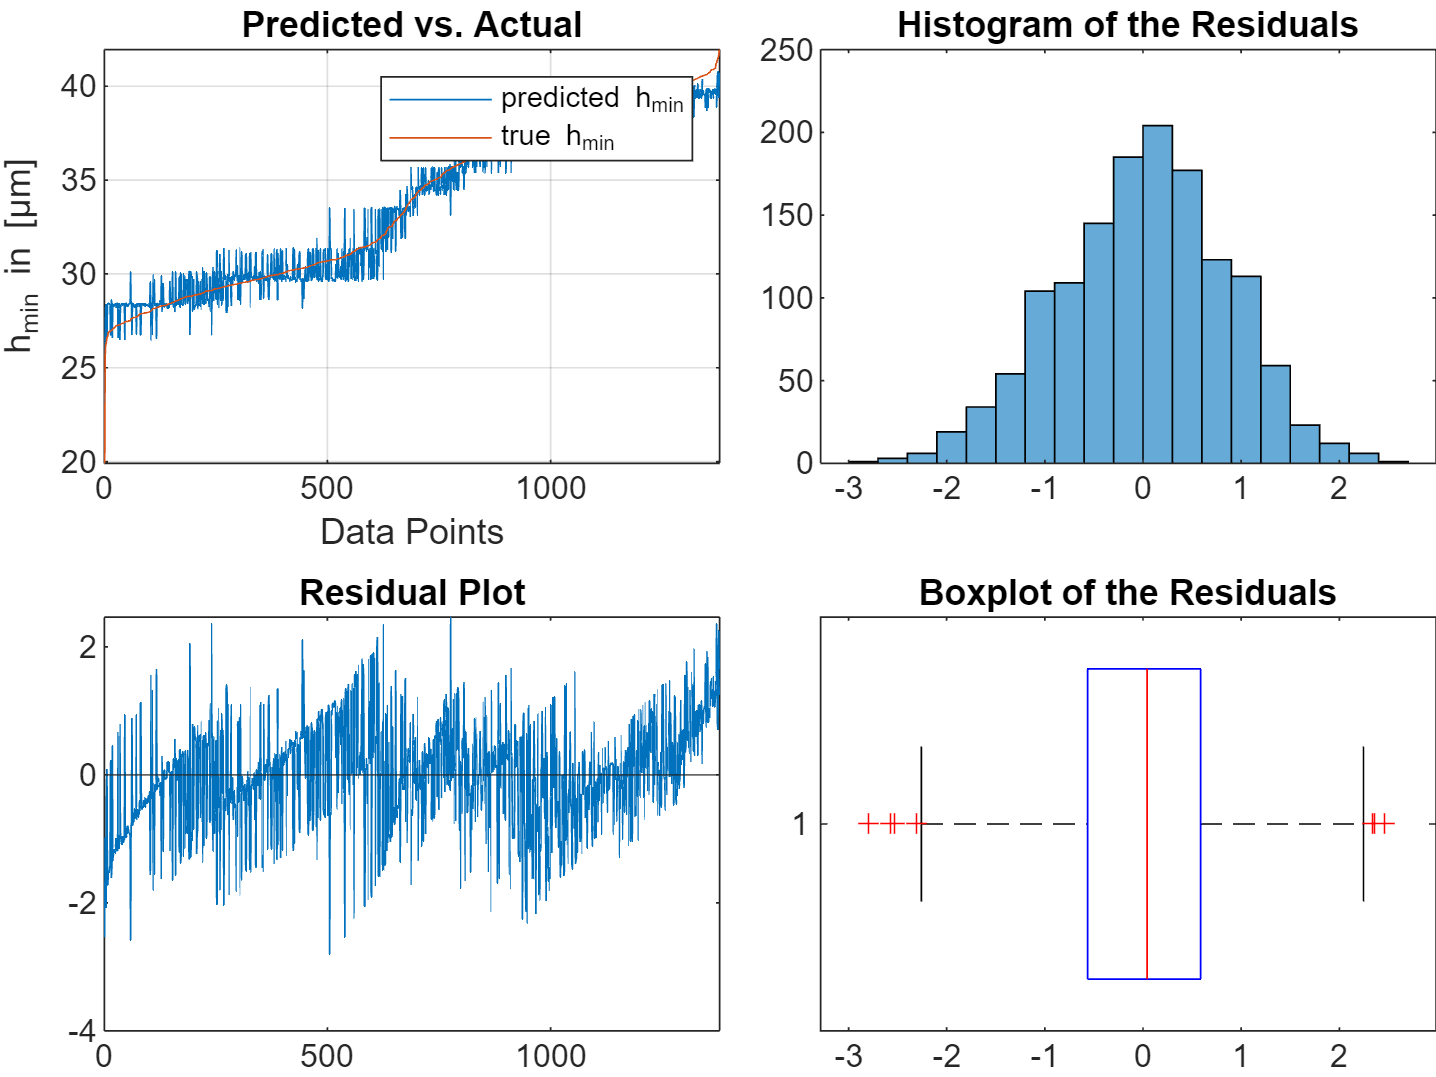

Number of Sensors: 3


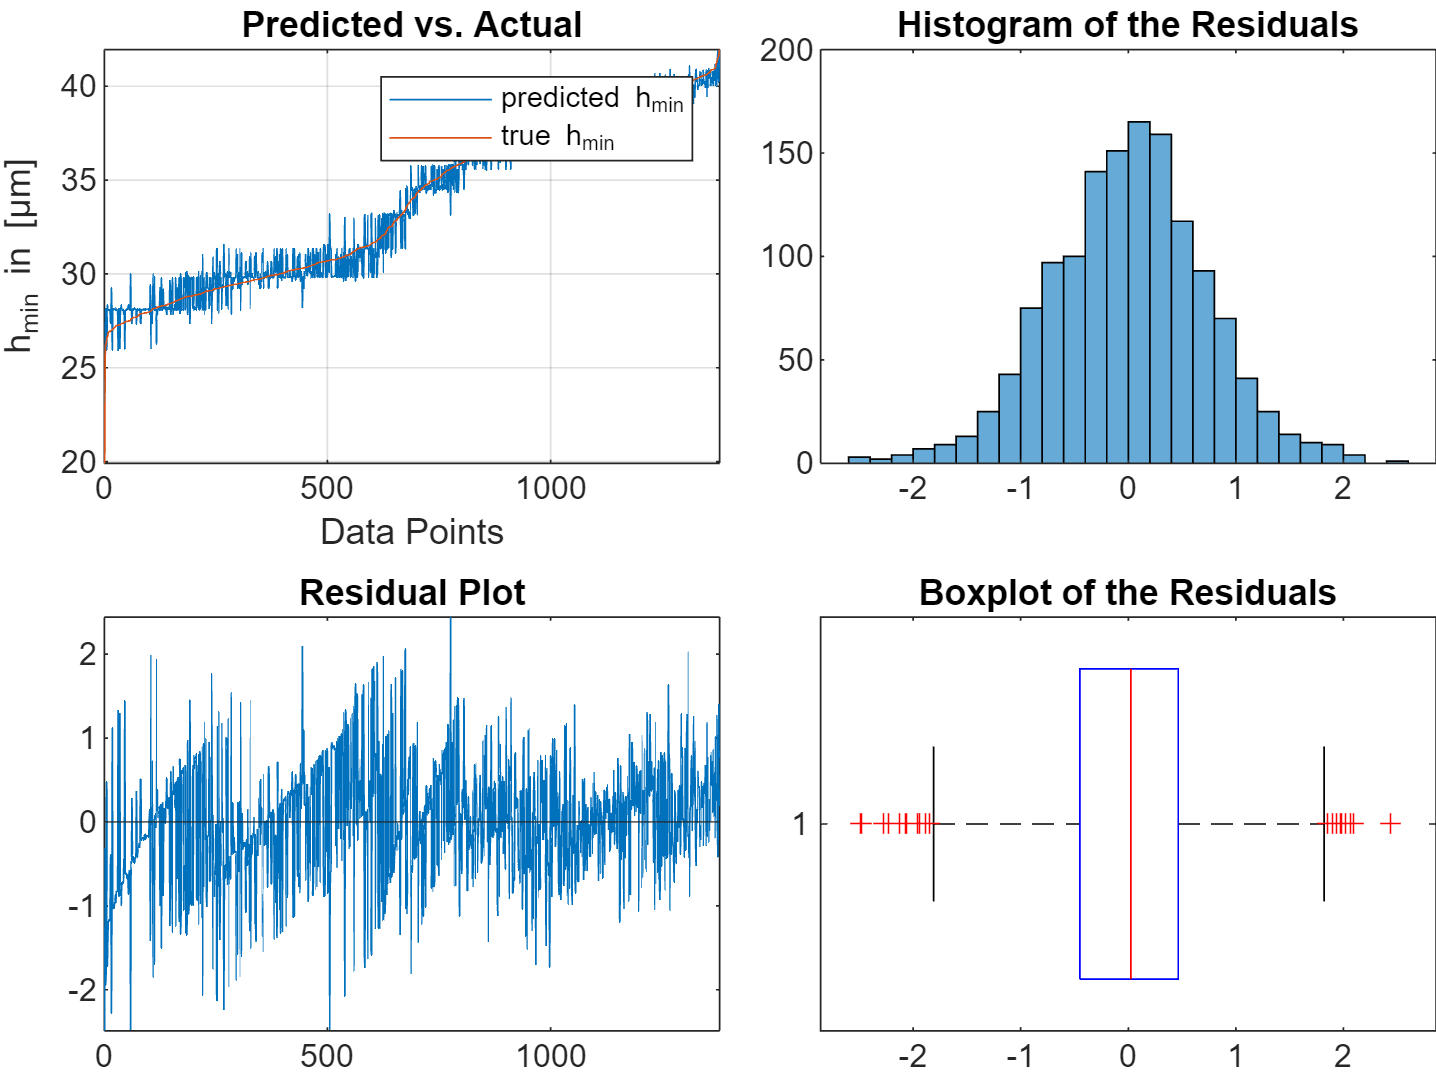

Number of Sensors: 4


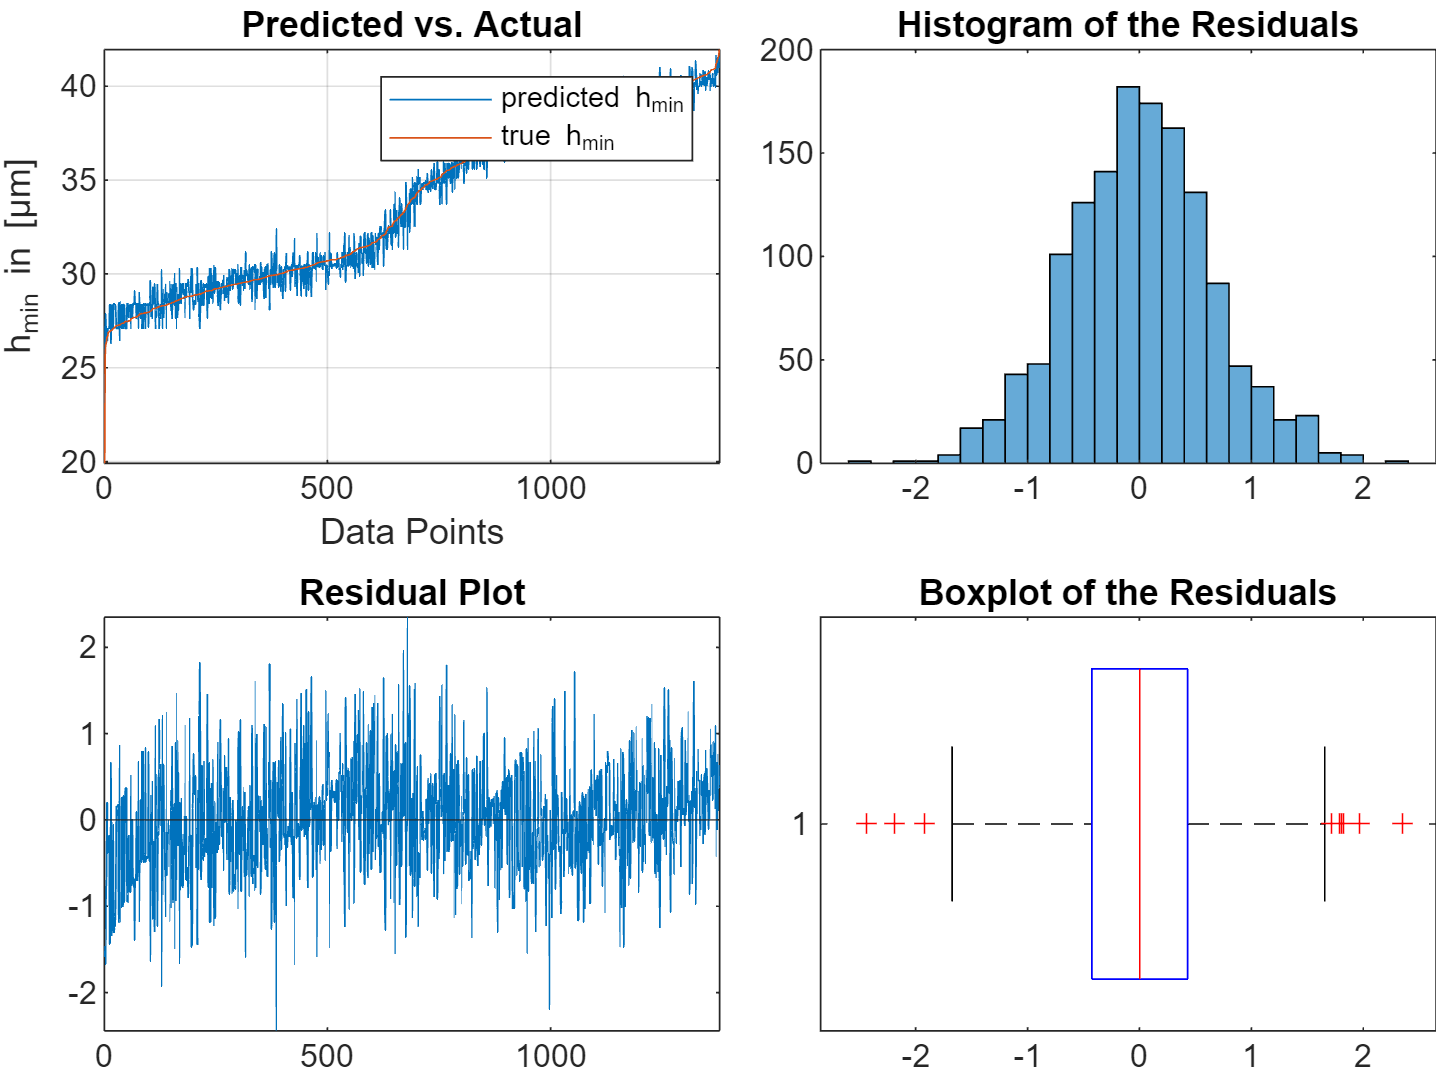

Number of Sensors: 5


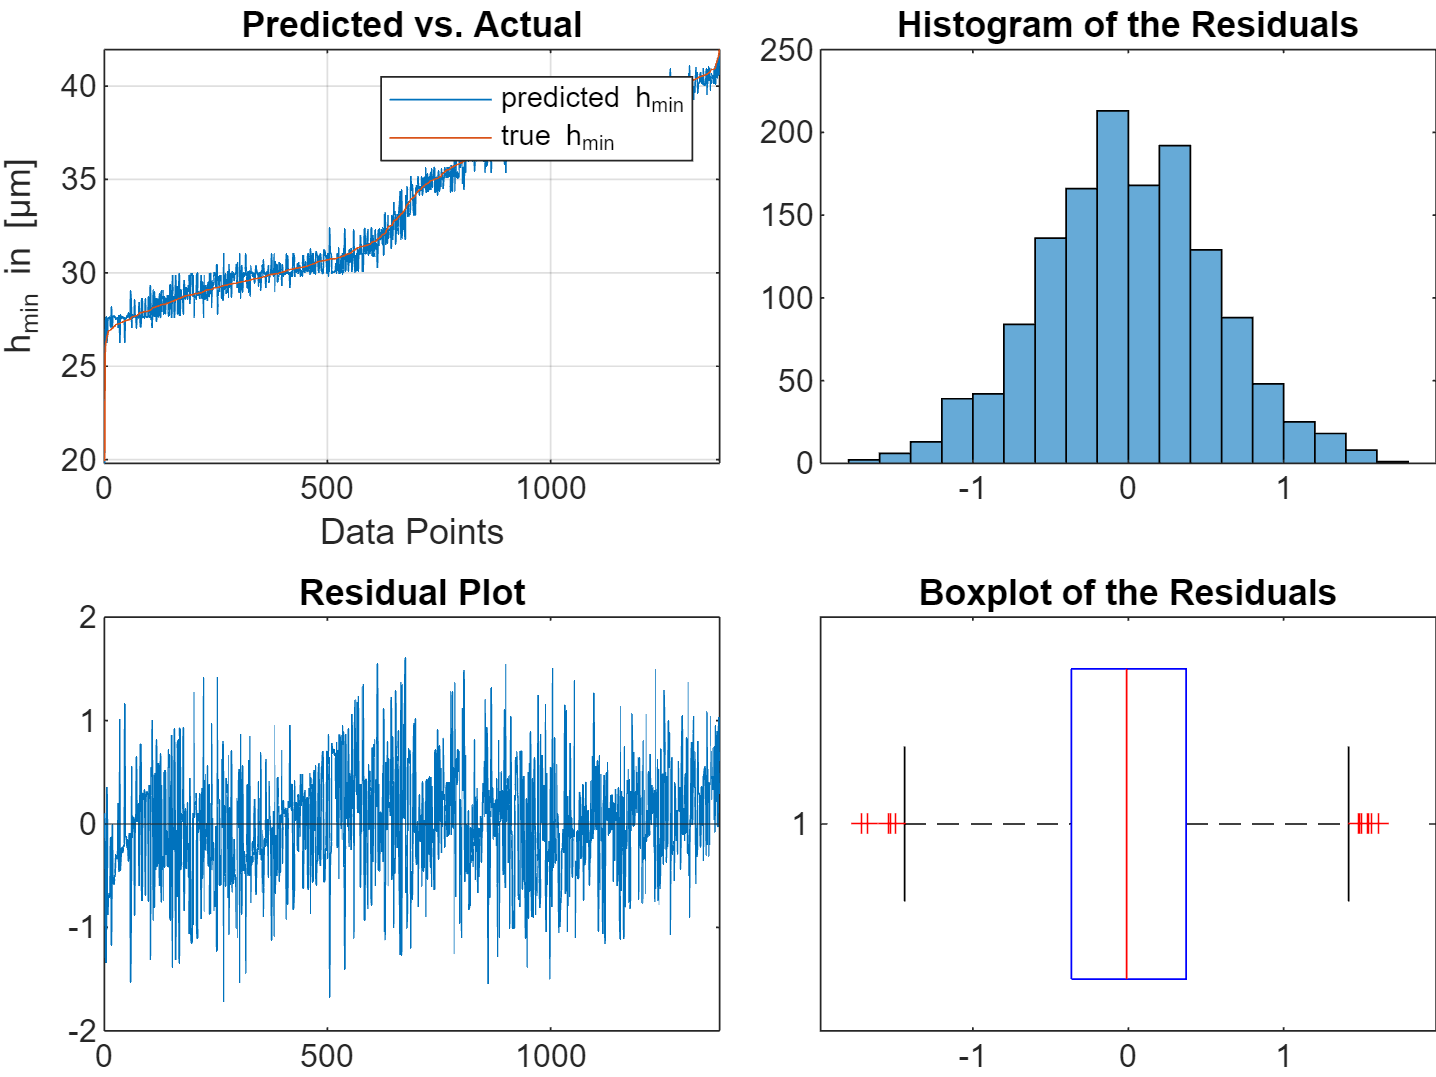

Number of Sensors: 6


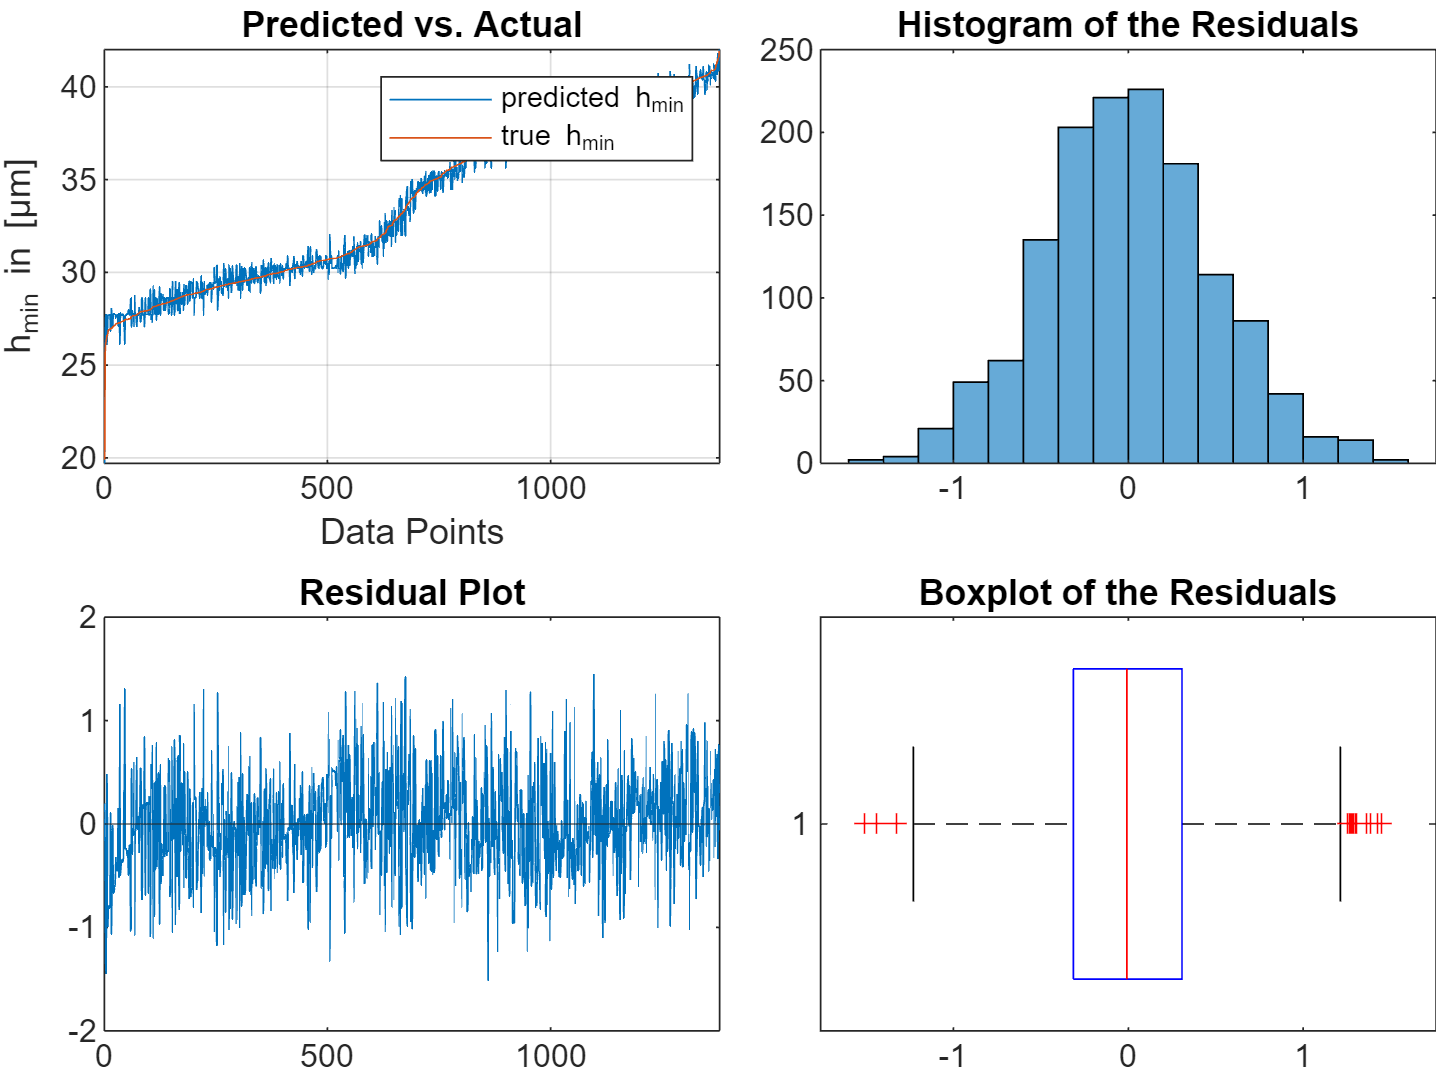

Number of Sensors: 7


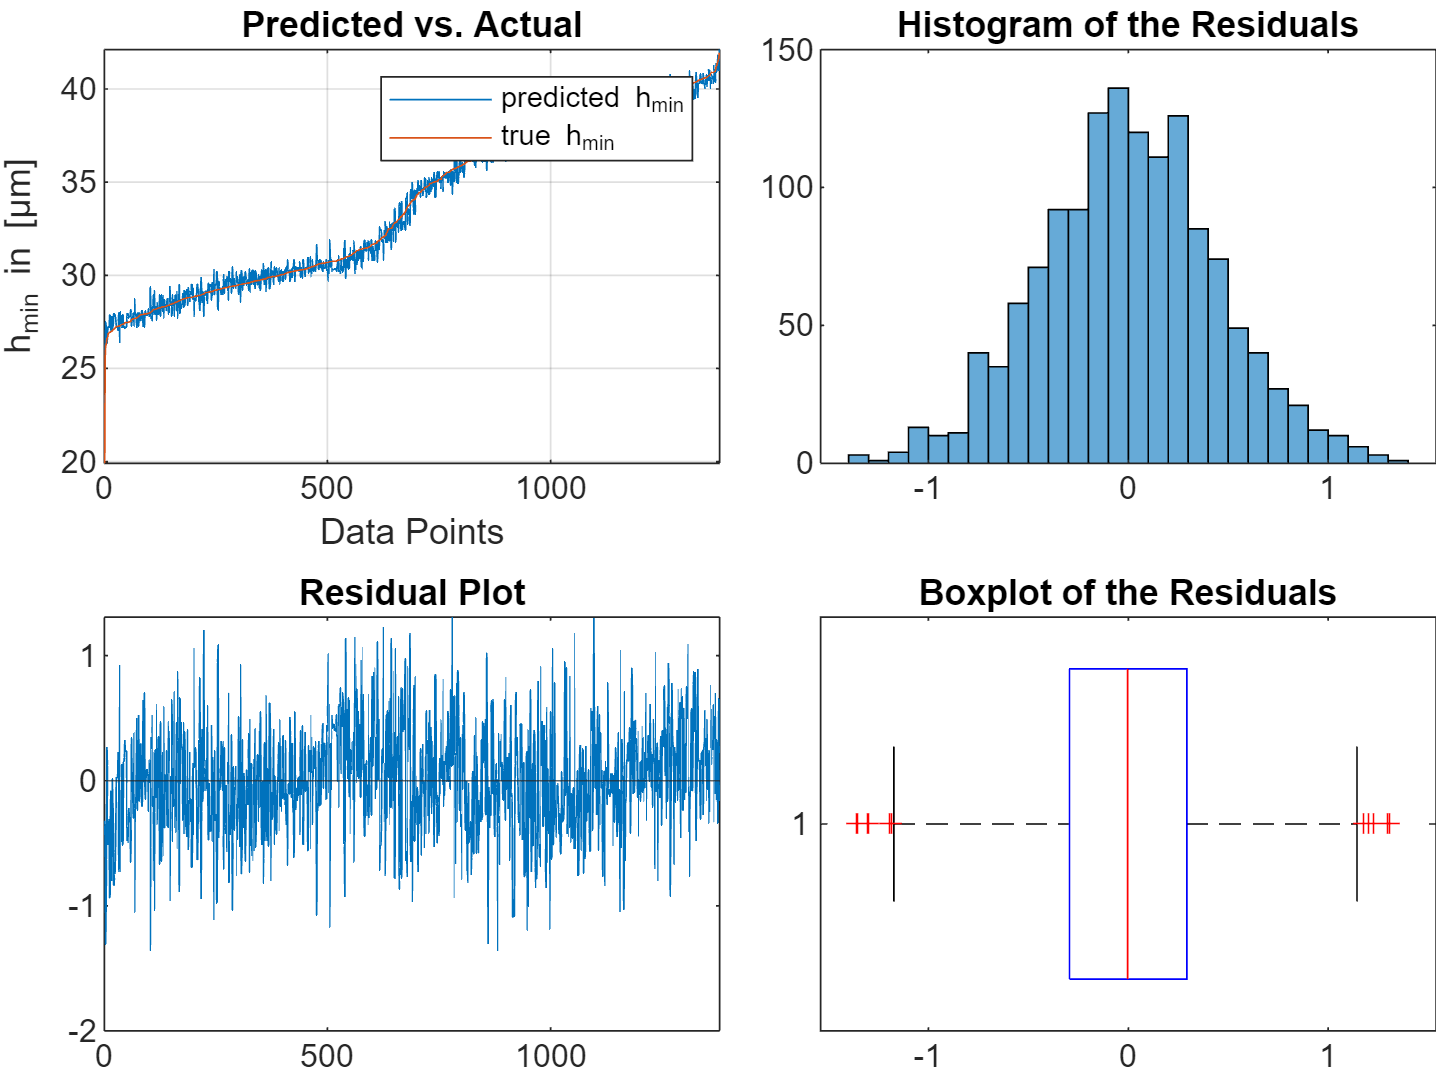

Number of Sensors: 8


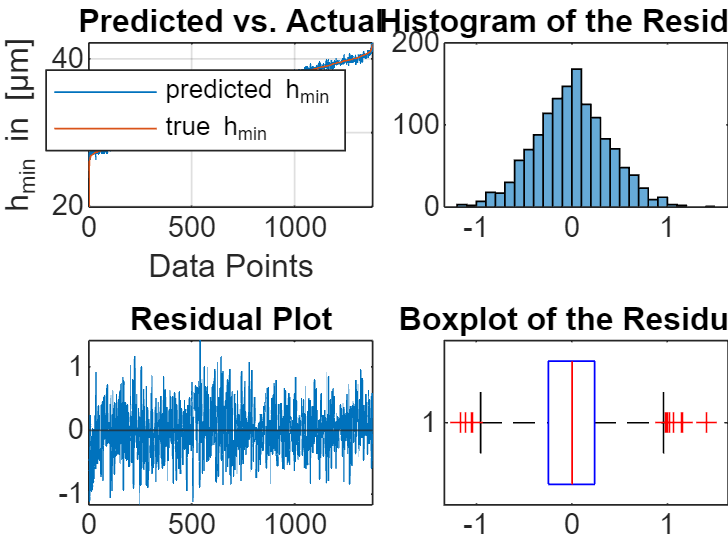

Number of Sensors: 9


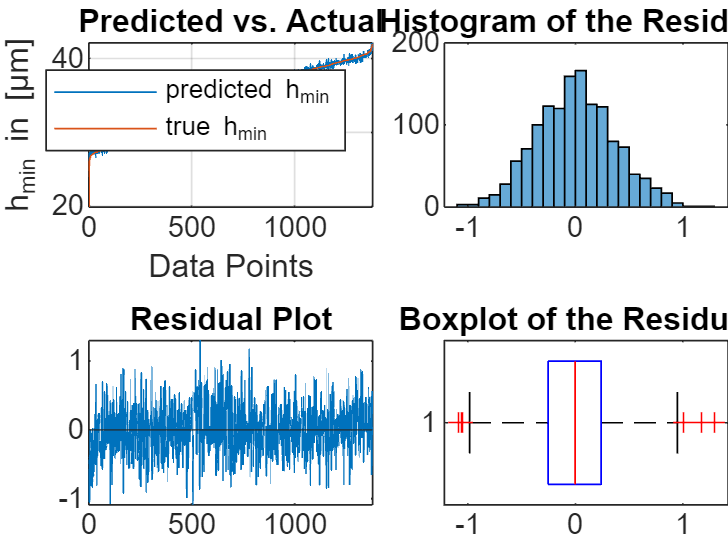

Number of Sensors: 10


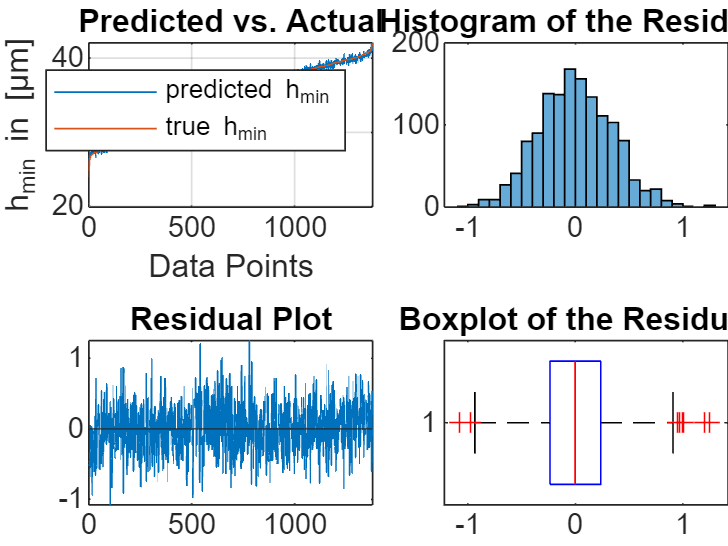

Number of Sensors: 11


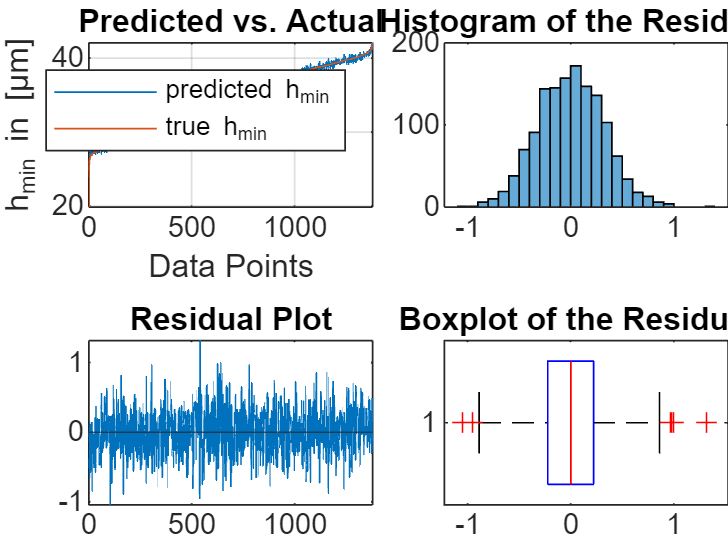

Number of Sensors: 12


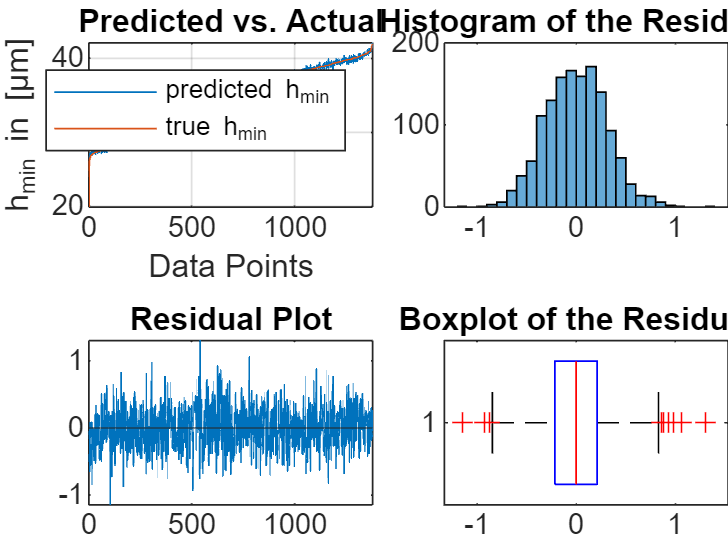

Number of Sensors: 13


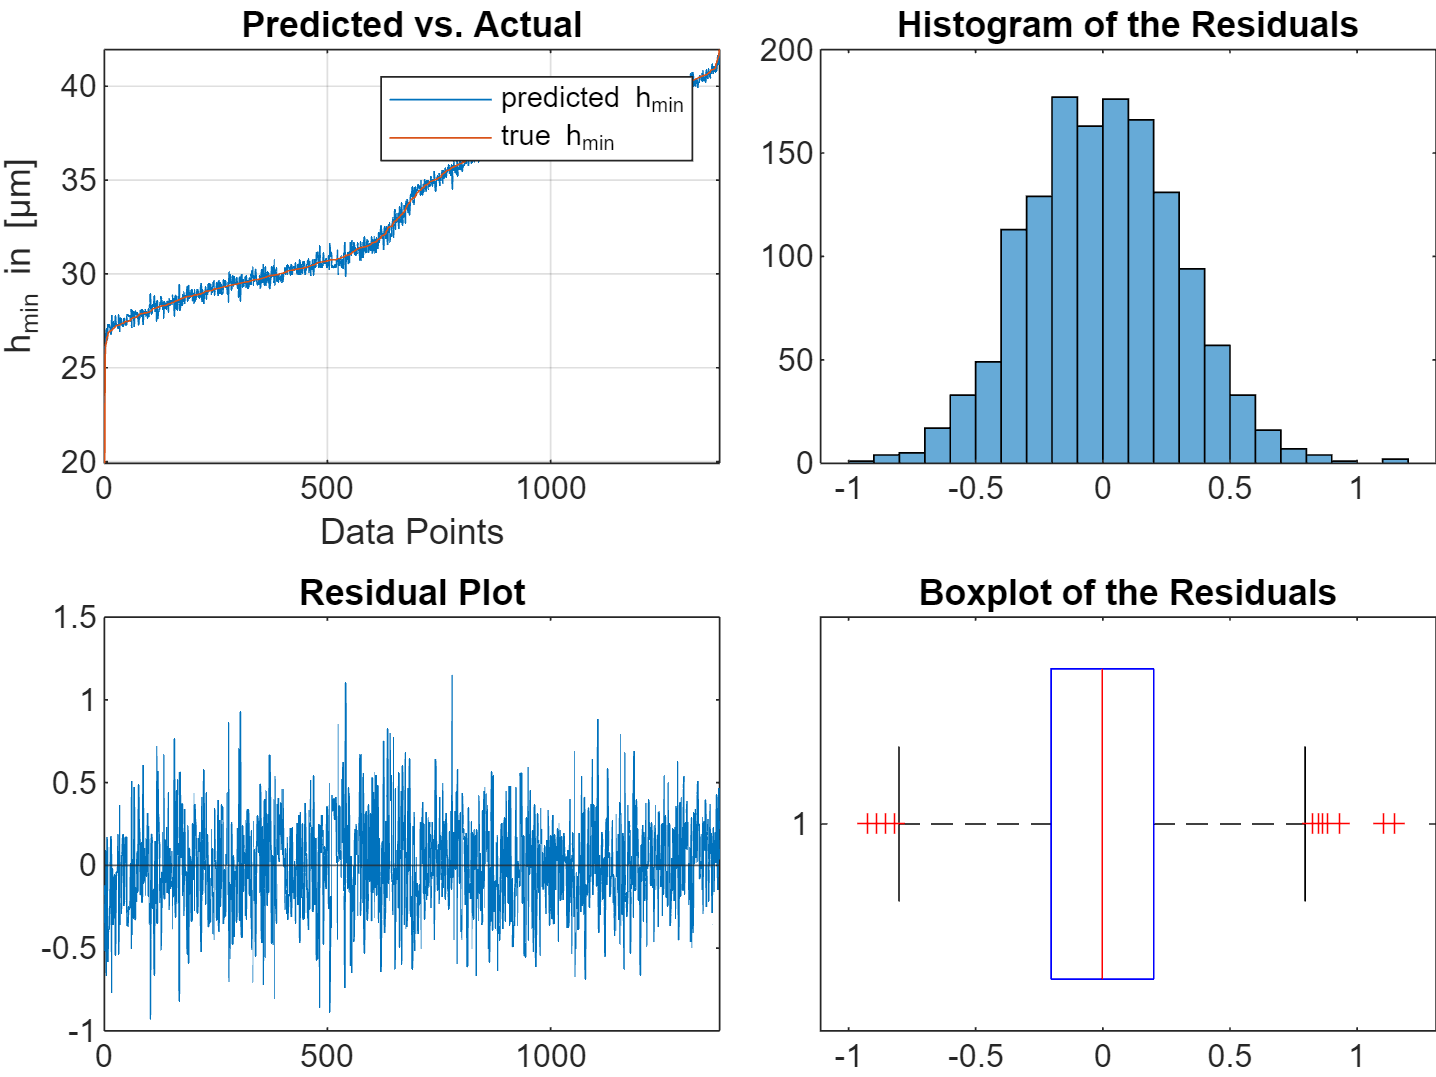

%load 'Stage 6 Regression Second Try'\'saved data'\combi_tbl.mat
load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat
load 'Stage 6 Regression Second Try'\'saved data'\'true values'\h_min_sorted.mat

for i = 1:numel(bestSubset)
    disp("Number of Sensors: "+i)
    h = bestSubset(i).h_min_fit;
    figure
    
    fig = tiledlayout(2,2,"TileSpacing","compact","Padding","tight");
    %title(fig,"Predicted vs. Actual")

    ax1 = nexttile; % predicted vs. actual
    plot(1:length(h),h)
    hold on, grid on
    plot(1:length(h),h_min_sorted{:,:})
    %plot(1:length(h),combi_tbl.h_min_lim)
    hold off
    ylabel("h_{min} in [μm]")
    xlabel("Data Points"),xlim(ax1,[0,length(h)+1])
    legend("predicted h_{min}","true h_{min}")
    title(ax1,"Predicted vs. Actual")

    ax3 = nexttile; % histogram of the residuals
    histogram(bestSubset(i).Residuals);
    title("Histogram of the Residuals")
    
    ax2 = nexttile; % residual plot
    plot(1:length(h),bestSubset(i).Residuals)
    title(ax2,"Residual Plot")
    yline(0),xlim(ax2,[0,length(h)+1])

    ax4 = nexttile;
    boxplot(bestSubset(i).Residuals,"Orientation","horizontal")
    title(ax4,"Boxplot of the Residuals")

    linkaxes([ax1 ax2],'x');
    linkaxes([ax3 ax4],'x');

    
end

Best subset selection with Ridge regression applied